clear a1_vector a2_vector a3_vector var_vector
array1 = [1.01 1.04 1.05 0.98 0.99 1.01 1.07 1.10 1.15 1.12 1.13 1.20 1.21]';

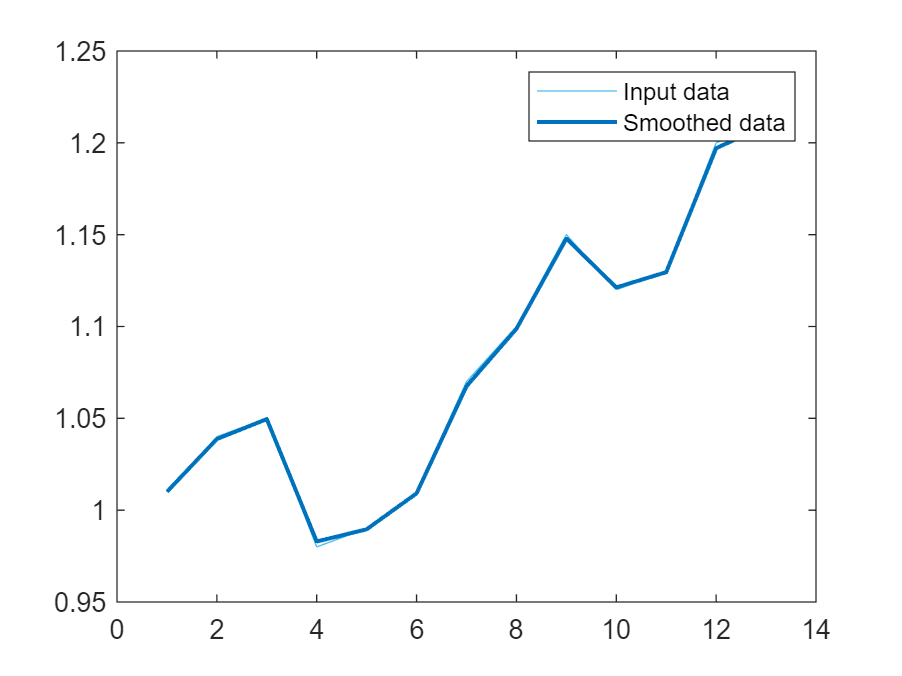

% Smooth input data
smoothedData = smoothdata(array1,"gaussian","SmoothingFactor",0.05);

% Display results
clf
plot(array1,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(smoothedData,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend

array1 = [array1 ;array1+0.2 ;array1+0.4];
W = 13

W = 13



for startingSample = 1:length(array1)-W+1
    formatSpec = 'startingSample is now %4.2f\n';
    fprintf(formatSpec,startingSample)
    currentIndices1 = startingSample:startingSample+W-1;
    array1Smooth = smooth(array1(currentIndices1));
    array1Detrended = array1(currentIndices1) - array1Smooth;
    [pcf, lags] = parcorr(array1Detrended);
    [acf, lags] = autocorr(array1Detrended);
    a2_vector(startingSample) = pcf(2);
    a3_vector(startingSample) = acf(2);
    sys = ar(array1Detrended, 1, 'ls');
    [num,den] = tfdata(sys,'v');
%     a1 = abs(den(2));
    a1 = den(2);
    a1_vector(startingSample) = a1;
end

startingSample is now 1.00
startingSample is now 2.00
startingSample is now 3.00
startingSample is now 4.00
startingSample is now 5.00
startingSample is now 6.00
startingSample is now 7.00
startingSample is now 8.00
startingSample is now 9.00
startingSample is now 10.00
startingSample is now 11.00
startingSample is now 12.00
startingSample is now 13.00
startingSample is now 14.00
startingSample is now 15.00
startingSample is now 16.00
startingSample is now 17.00
startingSample is now 18.00
startingSample is now 19.00
startingSample is now 20.00
startingSample is now 21.00
startingSample is now 22.00
startingSample is now 23.00
startingSample is now 24.00
startingSample is now 25.00
startingSample is now 26.00
startingSample is now 27.00


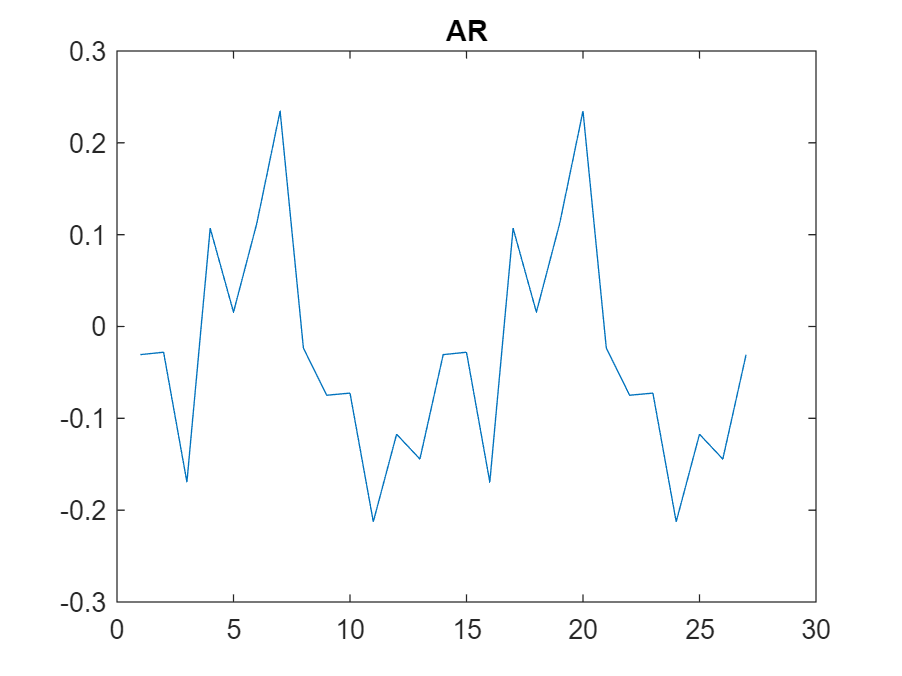


plot(a1_vector)
title('AR')

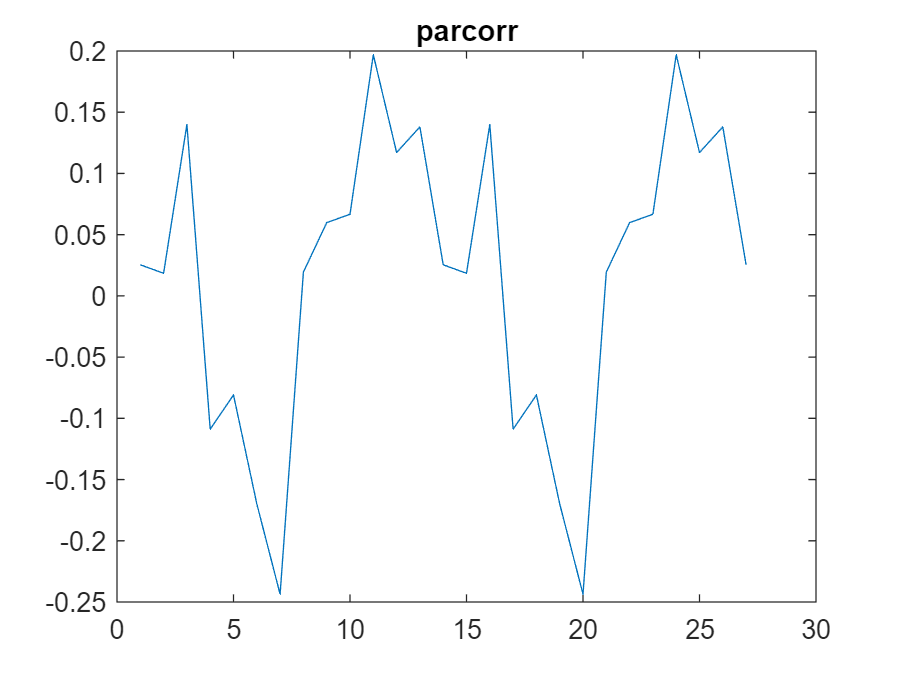

plot(a2_vector)
title('parcorr')

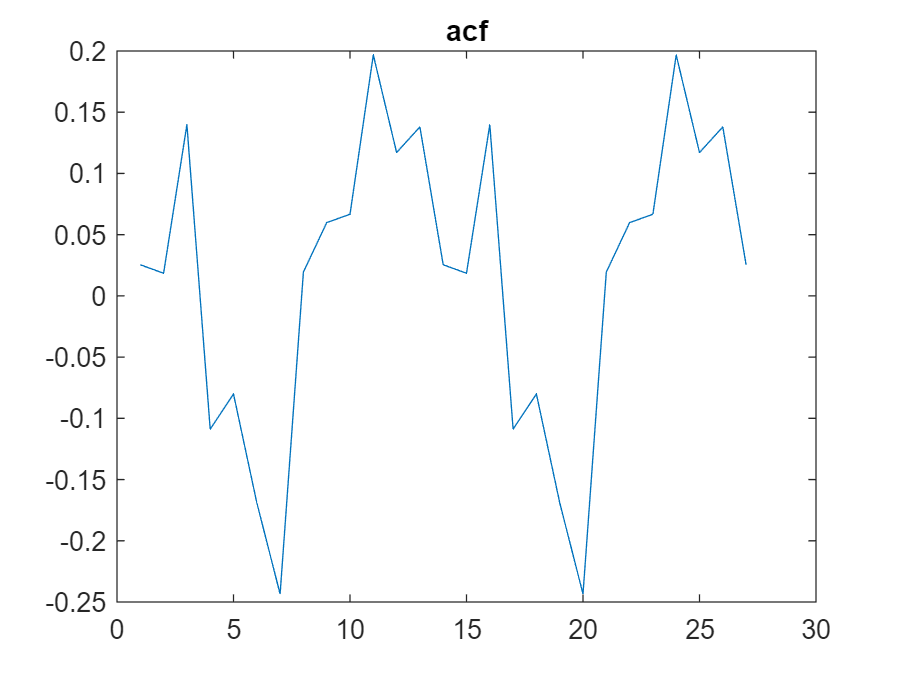

plot(a3_vector)
title('acf')